# **Computer Assignment 3 - Signals & Systems - Dr Akhavan**

## ** Amirali Dehghani - 810102443**

### **Question 1**

clc, clearvars, close all;

#### 1 - 1) Creating Mapset

Nch = 32;
mapset = cell(2,Nch);
Alphabet ='abcdefghijklmnopqrstuvwxyz .,!";';
for i = 1:Nch
    mapset{1,i}=Alphabet(i);
    mapset{2,i}=dec2bin(i-1,5);
end

#### 1 - 2) Encoding a picture

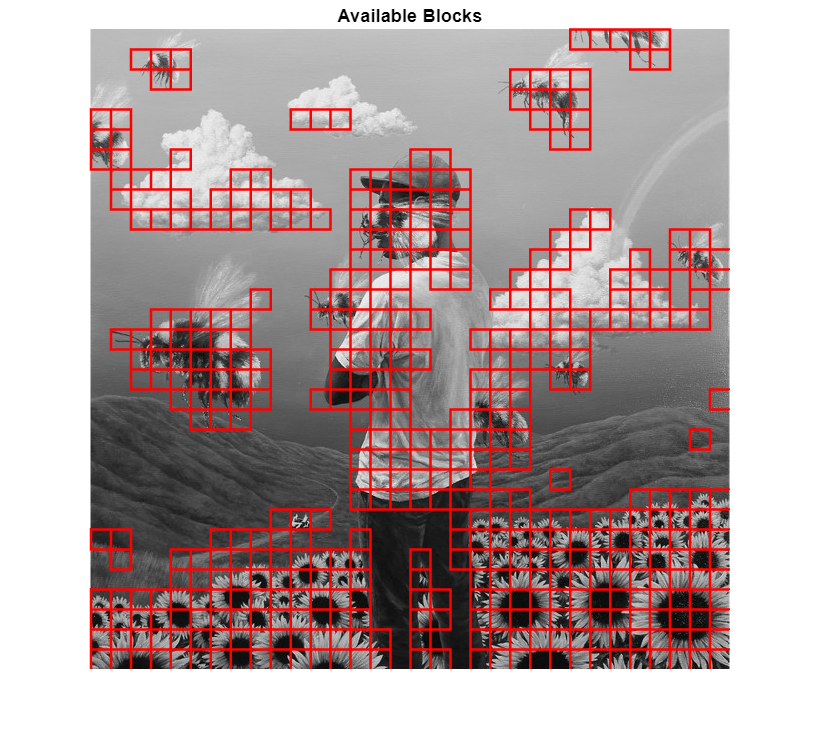

[file, path] = uigetfile({'*.jpg;*.png'}, "Choose your picture: ");
picture = imread([path, file]);
picture = rgb2gray(picture);
message = 'signal;';
codedPicture = coding(picture, message, mapset);

#### Additional) Showing available blocks in photo

#### 1 - 3) Showing original picture and coded picture

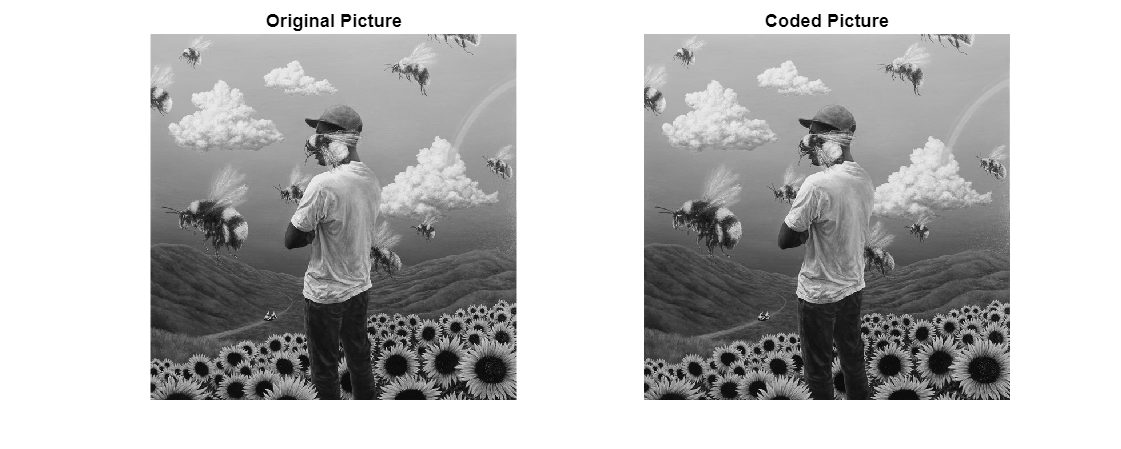

figure('Position', [0 0 1000 400]);
plot1 = subplot(1,2,1);
imshow(picture);
title('Original Picture');
plot2 = subplot(1,2,2);
imshow(codedPicture);
title('Coded Picture');

#### 1 - 4) Decoding the picture

blockSize = 20;
threshold = 100;
message = decoding(codedPicture, mapset, blockSize, threshold);
fprintf('Hidden message is : "%s"', message);

Hidden message is : "signal;"

#### 1 - 5 ) If noise is unintentionally added to the image, can we still decode it?

### Question 2

clc, clearvars, close all;

#### 2 - 1)

load("DataFit.mat");

#### 2 - 2)

minError = inf;
bestParameters = containers.Map;

tic;
for a0 = 0.01:0.01:1
    for w0 = 0:pi/10:10*pi
        for phi0 = 0:pi/100:2*pi
            y_pred = a0 * sin(w0 * x + phi0);
            error = sum((y - y_pred).^2);
            if error < minError
                minError = error;
                bestParameters('a0') = a0;
                bestParameters('w0') = w0;
                bestParameters('phi0') = phi0;
            end
        end
    end
end
toc;

Elapsed time is 23.525600 seconds.


fprintf('Best parameters: a0=%.4f, ω0=%.4f, φ0=%.4f\n', bestParameters('a0'), bestParameters('w0'), bestParameters('phi0'));

Best parameters: a0=0.5000, ω0=6.2832, φ0=0.5027


#### 2 - 3)

minError = inf;
bestParameters = containers.Map;
tic;
for a0 = 0.1:0.1:1
    for w0 = 0:pi:10*pi
        for phi0 = 0:pi/10:2*pi
            y_pred = a0 * sin(w0 * x + phi0);
            error = sum((y - y_pred).^2);
            if error < minError
                minError = error;
                bestParameters('a0') = a0;
                bestParameters('w0') = w0;
                bestParameters('phi0') = phi0;
            end
        end
    end
end

minError = inf;
finalParameters = containers.Map;
range_a0 = max(bestParameters('a0')-0.005,0.01):0.01:min(bestParameters('a0')+0.005,1);
range_w0 = max(bestParameters('w0')-pi/20,0):pi/10:min(bestParameters('w0')+pi/20,10*pi);
range_phi0 = max(bestParameters('phi0')-pi/200,0):pi/100:min(bestParameters('phi0')+pi/200,2*pi);

for a0 = range_a0
    for w0 = range_w0
        for phi0 = range_phi0
            y_pred = a0 * sin(w0 * x + phi0);
            error = sum((y - y_pred).^2);
            if error < minError
                minError = error;
                finalParameters('a0') = a0;
                finalParameters('w0') = w0;
                finalParameters('phi0') = phi0;
            end
        end
    end
end
toc;

Elapsed time is 0.044634 seconds.


fprintf('Best parameters: a0=%.4f, ω0=%.4f, φ0=%.4f\n', finalParameters('a0'), finalParameters('w0'), finalParameters('phi0'));

Best parameters: a0=0.4950, ω0=6.1261, φ0=0.6440


#### 2 - 4)

tic;
mu = 0.001;
tol = 1e-5;

z = [0.1; 0; 0];
while true
    a = z(1);
    omega = z(2);
    phi = z(3);
    
    grad_a = -2 * sum((y - a.*sin(omega.*x + phi)) .* sin(omega.*x + phi));
    grad_omega = -2 * sum((y - a.*sin(omega.*x + phi)) .* a.*x.*cos(omega.*x + phi));
    grad_phi = -2 * sum((y - a.*sin(omega.*x + phi)) .* a.*cos(omega.*x + phi));
    gradient = [grad_a; grad_omega; grad_phi];
    
    z_new = z - mu * gradient;
    
    if norm(z_new - z) < tol || norm(gradient) < tol
        break
    end
    z = z_new;
end
toc;

Elapsed time is 26.673584 seconds.


z

z =     0.1727
   -0.0497
    0.2705


### Question 3

clc, clearvars, close all;

#### 3 - 1)

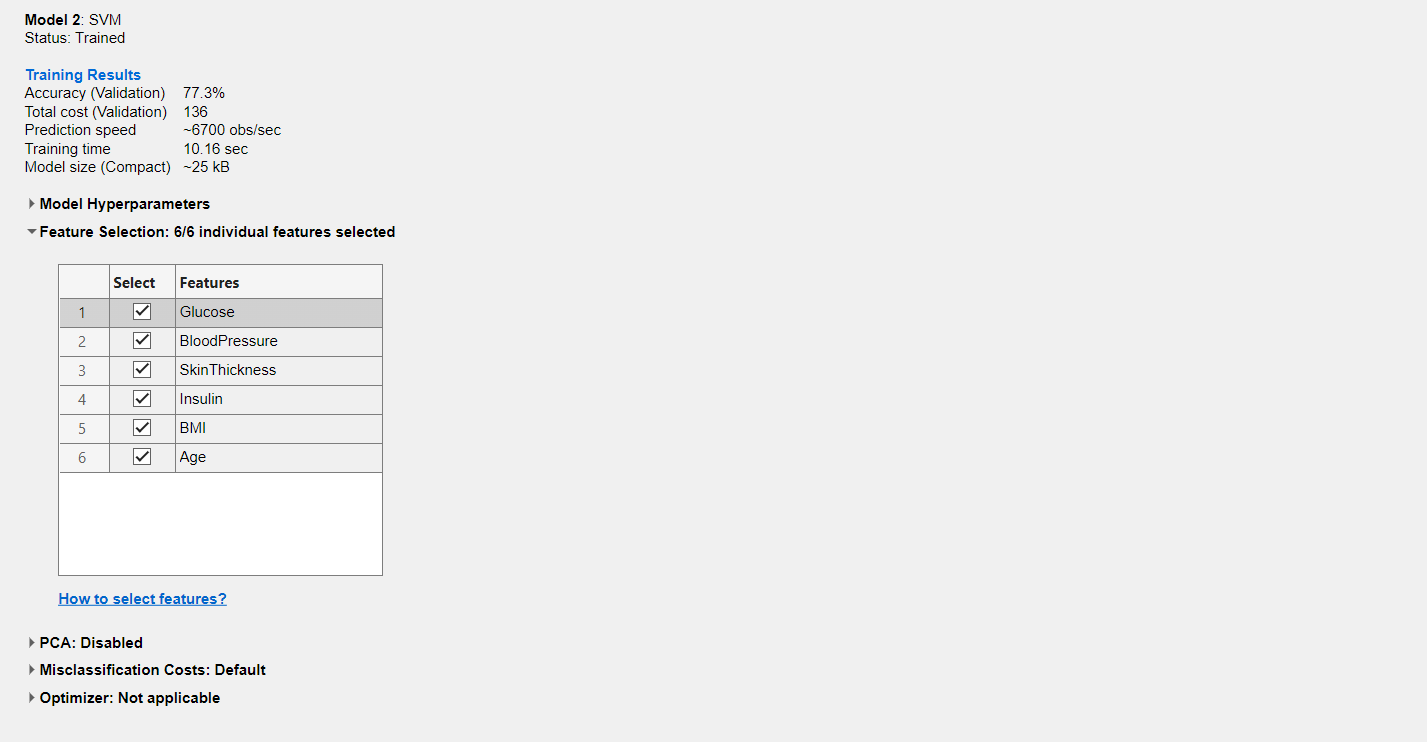

#### 3 - 2)

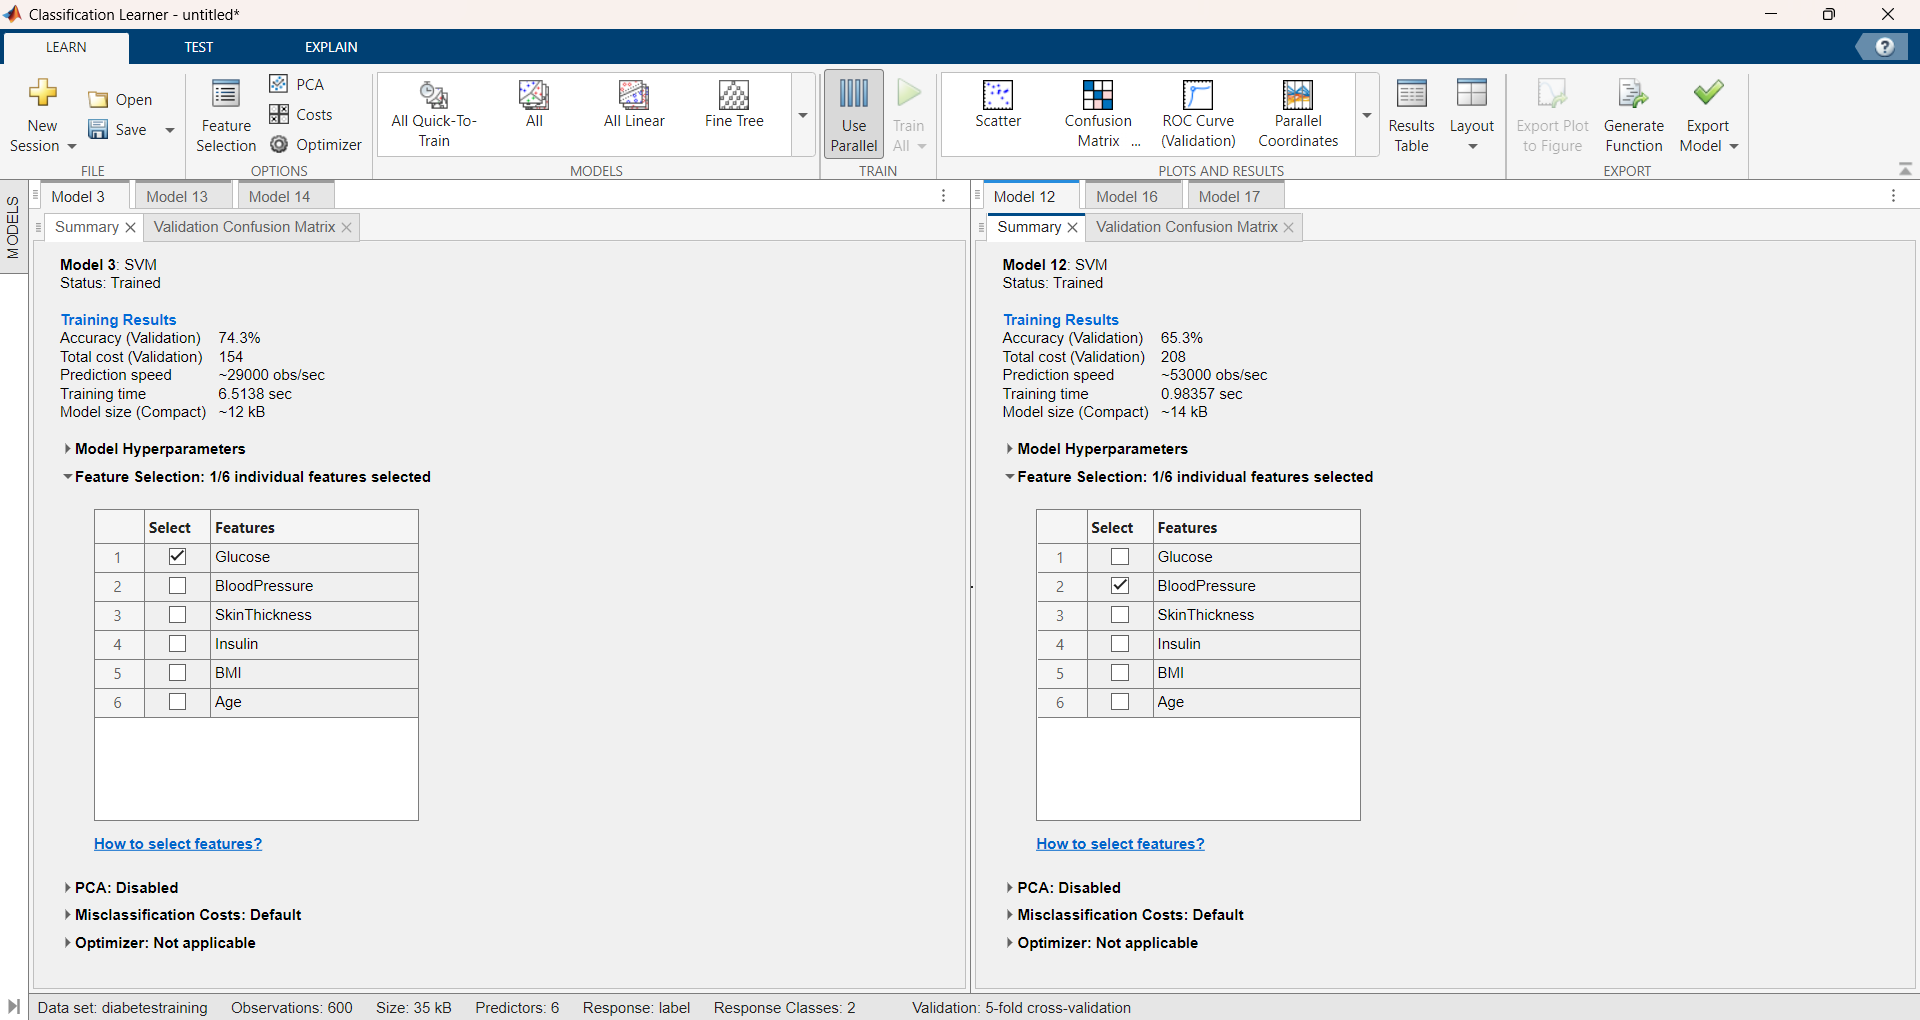

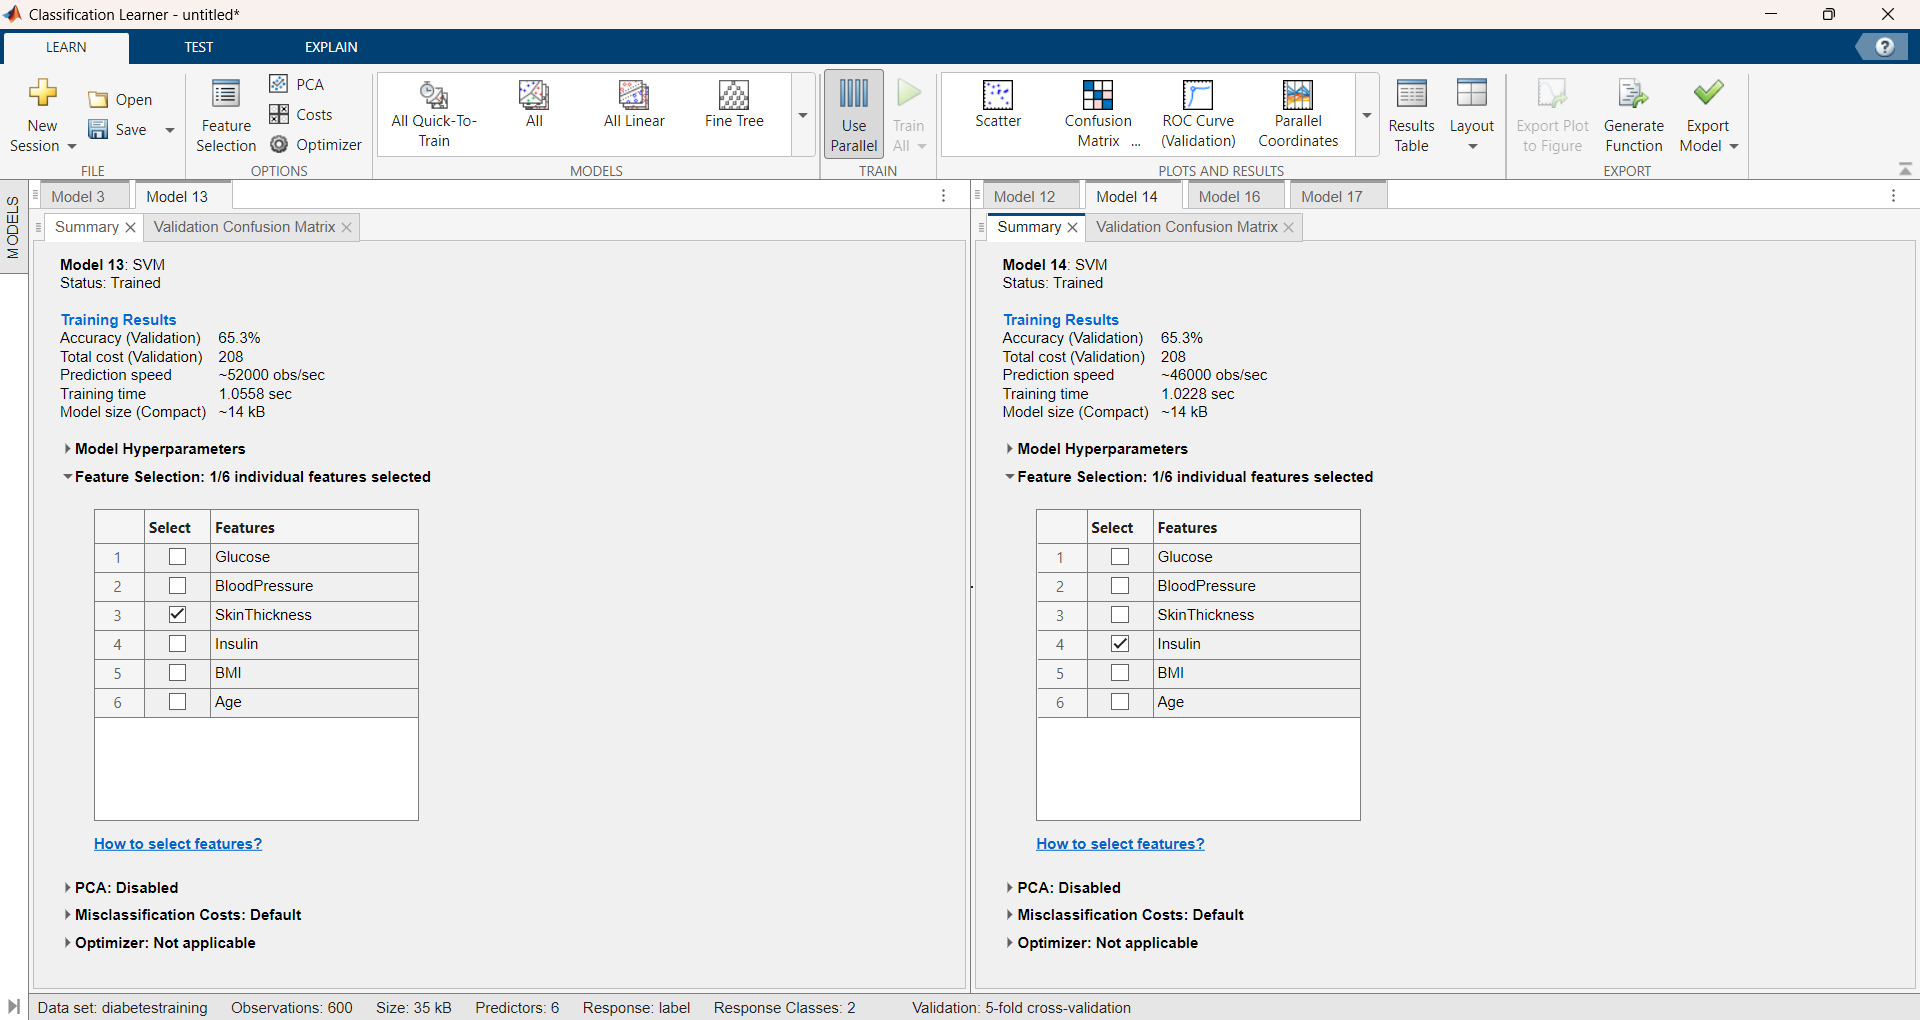

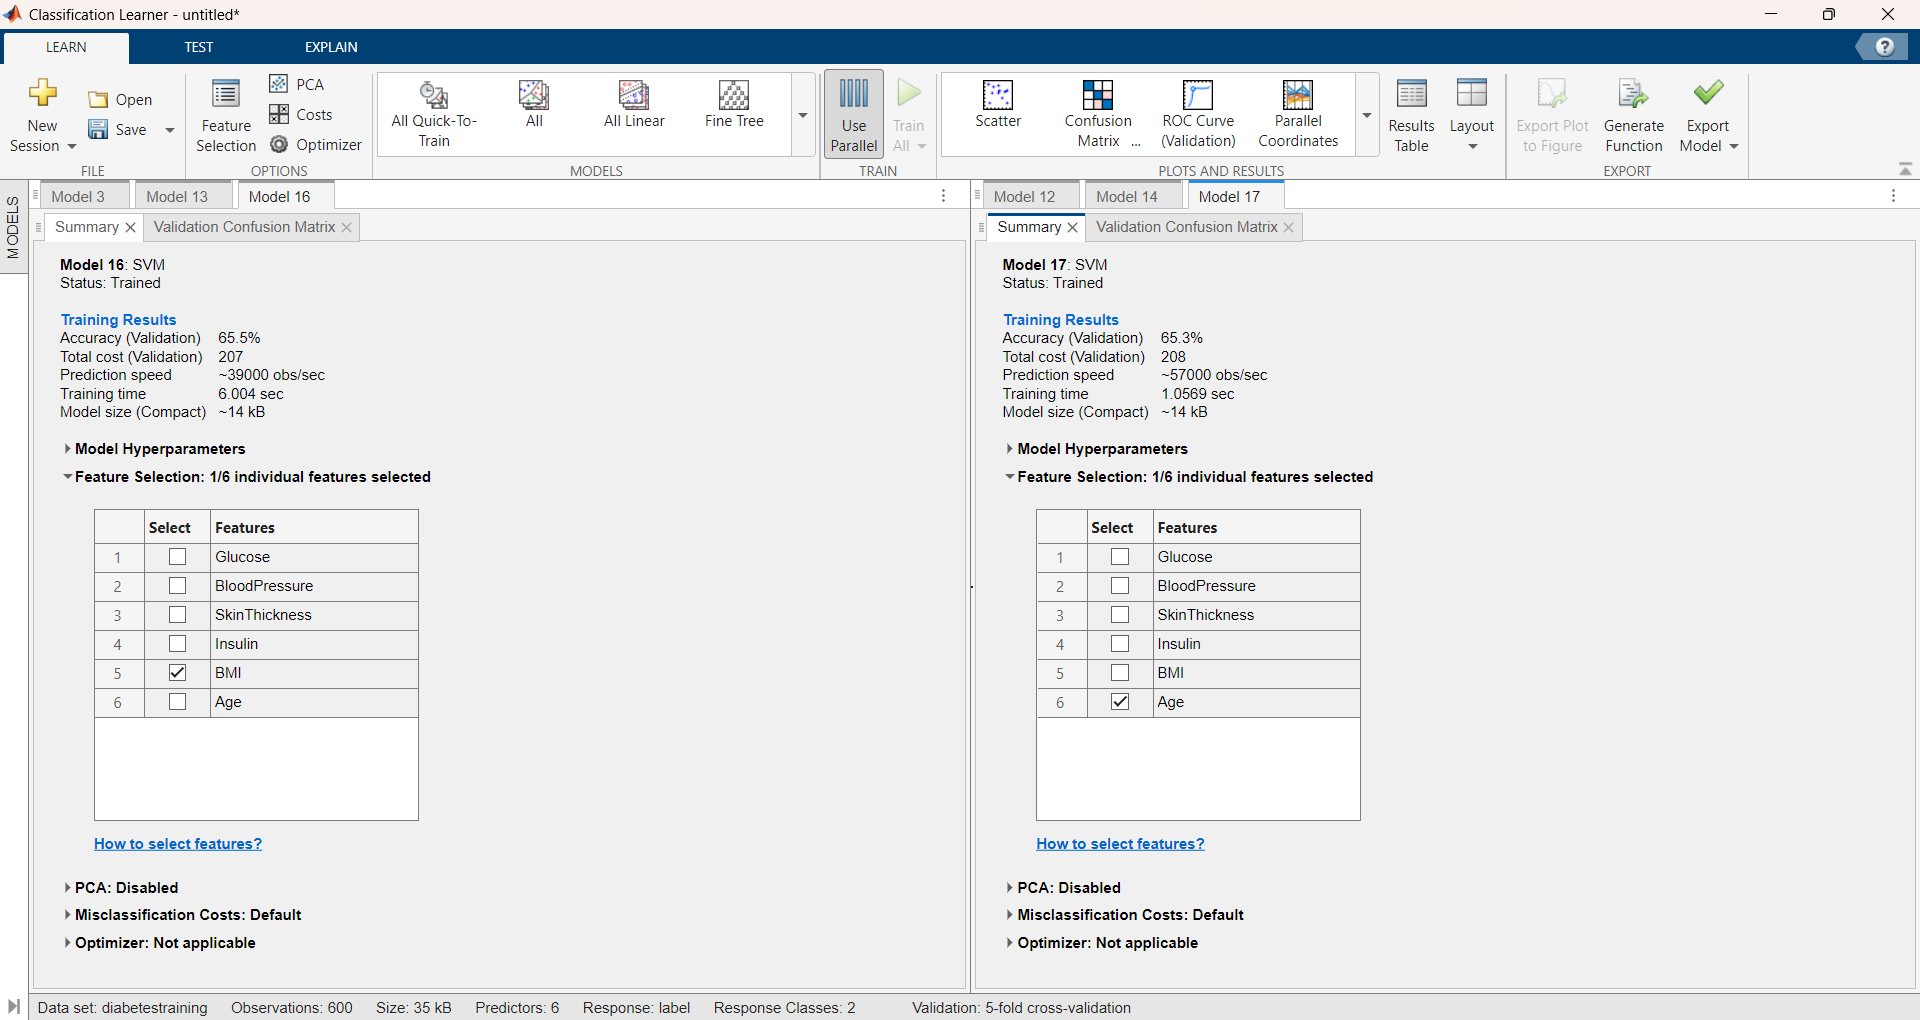

#### 3 - 3)

load('TrainedModel.mat');
dataset = readtable('diabetes-training.csv');
labels = dataset(:, end);
features = dataset(:, 1 : end-1);
predictions = TrainedModel.predictFcn(features);
accuracy = mean(predictions == labels).*100;
disp(accuracy);

#### 3 - 4)

dataset = readtable('diabetes-validation.csv');
labels = dataset(:, end);
features = dataset(:, 1 : end-1);
predictions = TrainedModel.predictFcn(features);
accuracy = mean(predictions == labels).*100;
disp(accuracy);

### Part 4

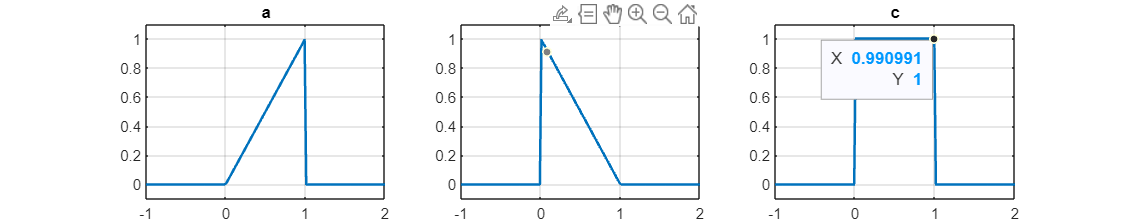

clc, clearvars, close all;

t = linspace(-10, 10, 1000);
a = (t >= 0 & t < 1) .* t;
b = (t >= 0 & t < 1) .* (1 - t);
c = (t >= 0 & t <= 1);

signals = {'a', 'b', 'c'};
data = {a, b, c};
figure('Position',[0, 0 1000, 200]);
idx = 1;
for i = 1:3
    subplot(1, 3, i);
    xlim([-1, 3]);
    plot(t, data{i}, 'LineWidth', 1.5);
    title(signals{i});
    grid on;
    xlim([-1, 2]);
    ylim([-0.1,1.1])
end

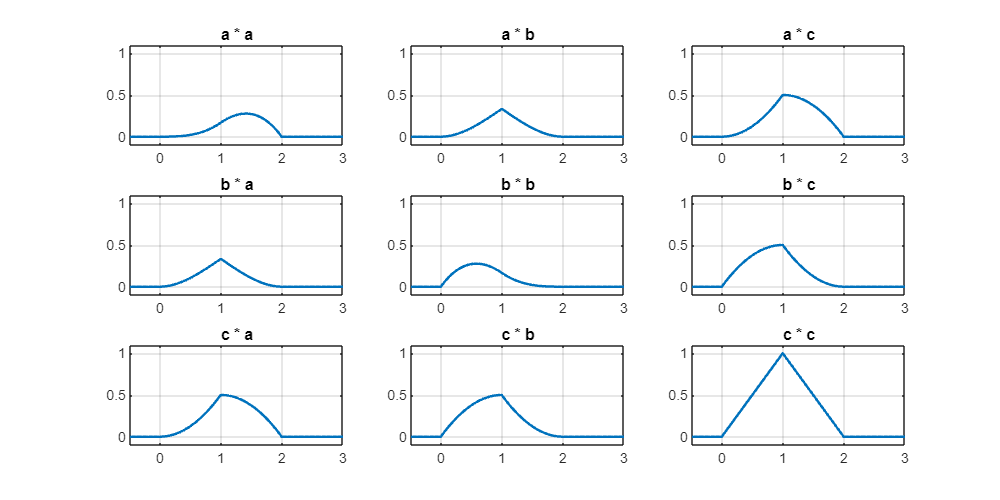

figure('Position',[0, 0, 800, 400]);
idx = 1;
for i = 1:3
    for j = 1:3
        conv_result = conv(data{i}, data{j}, 'same') * (t(2) - t(1));
        subplot(3, 3, idx);
        plot(t, conv_result, 'LineWidth', 1.5);
        title([signals{i}, ' * ', signals{j}]);
        xlim([-0.5,3]);
        ylim([-0.1, 1.1]);
        grid on;
        idx = idx + 1;
    end
end

### Functions

function codedPicture = coding(picture, message, mapset)
    blockSize = 20;
    threshold = 70;
    codedPicture = picture;
    [height, width] = size(picture);
    roundedSize = [floor(height / blockSize) * blockSize, floor(width / blockSize) * blockSize];
    messageLength = length(message);
    binarizedMessage = message2binary(message, mapset);
    availableBlocks = sortBlocks(picture, roundedSize, blockSize, threshold);
    numOfAvailableBlocks = length(availableBlocks);
    if numOfAvailableBlocks < messageLength
        fprintf("You can only fit %d characters in this picture but your message has %d characters.\n", numOfAvailableBlocks, messageLength);
        codedPicture = 1;
        return
    end
    visualizeBlocks(picture, blockSize, threshold);
    messageIndex = 1;
    for i = 1:numOfAvailableBlocks
        block = availableBlocks{i};
        pixels = block('pixels');
        position = block('position'); x = position(1); y = position(2);
        for j = 1:blockSize
            for k = 1:blockSize
                if messageIndex > length(binarizedMessage)
                    break
                end
                pixel = pixels(j, k);
                binarizedPixel = dec2bin(pixel, 8);
                binarizedPixel(end) = binarizedMessage(messageIndex);

                pixels(j, k) = bin2dec(binarizedPixel);
                messageIndex = messageIndex + 1;
            end
            if messageIndex > length(binarizedMessage)
                break
            end
        end
        codedPicture(x : x + blockSize-1, y : y + blockSize-1) = pixels; 
    end
end

function binarizedMessage = message2binary(message, mapset)
    binarizedMessage = '';
    for charInMessage = message
        found = false;
        for charInMapSet = mapset
            if charInMessage == charInMapSet{1};
                binarizedMessage = [binarizedMessage, charInMapSet{2}];
                found = true;
                break;
            end
        end
        if ~found
            fprintf('Character "%c" not found in mapset. Skipping...\n', charInMessage);
        end
    end
end

function message = decoding(codedPicture, mapset, blockSize, threshold)
    [height, width] = size(codedPicture);
    roundedSize = [floor(height / blockSize) * blockSize, floor(width / blockSize) * blockSize];
    codedBlocks = sortBlocks(codedPicture, roundedSize, blockSize, threshold);
    numOfcodedBlocks = length(codedBlocks);
    message = '';
    binarizedChar = '';
    character = '';
    for i = 1:numOfcodedBlocks
        block = codedBlocks{i};
        pixels = block('pixels');
        for j = 1:blockSize
            for k = 1:blockSize
                pixel = pixels(j, k);
                codedPixel = dec2bin(bitand(pixel, 1));
                binarizedChar = [binarizedChar, codedPixel];
                if length(binarizedChar) >= 5
                    character = getCharacter(binarizedChar, mapset);
                    message = [message, character];
                    binarizedChar = '';
                    if character == ';'
                        break
                    end
                end
            end
            if character == ';'
                break
            end
        end
        if character == ';'
            break
        end
    end
end

function availableBlocks = sortBlocks(picture, roundedSize, blockSize, threshold)
    blocks = {}; availableBlocks = {};
    for i = 1:blockSize:roundedSize(1)
        for j = 1:blockSize:roundedSize(2)
            pixels = picture(i:i + blockSize-1, j:j + blockSize-1);
            blockWithoutLSB = bitand(pixels, 254);
            contrast = max(blockWithoutLSB(:)) - min(blockWithoutLSB(:));
            block = containers.Map();
            block('pixels') = pixels;
            block('contrast') = contrast;
            block('position') = [i, j];
            if (contrast > threshold)
                availableBlocks{end+1} = block;
            end
            blocks{end+1} = block;
        end
    end
    contrasts = cellfun(@(block) block('contrast'), availableBlocks);
    [~, sortedIndices] = sort(contrasts, 'descend');
    availableBlocks = availableBlocks(sortedIndices);
end
function character = getCharacter(binary, mapset)
    for char = mapset
        if char{2} == binary
            character = char{1};
            break;
        end
    end 
end

function visualizeBlocks(picture, blockSize, threshold)
    [height, width] = size(picture);
    roundedSize = [floor(height / blockSize) * blockSize, floor(width / blockSize) * blockSize];
    availableBlocks = sortBlocks(picture, roundedSize, blockSize, threshold);

    figure, imshow(picture), title('Available Blocks');
    hold on;

    for i = 1:length(availableBlocks)
        block = availableBlocks{i};
        pos = block('position');
        x = pos(2);
        y = pos(1);
        rectangle('Position', [x, y, blockSize, blockSize], 'EdgeColor', 'r', 'LineWidth', 1.5);
    end
    
    hold off;
end